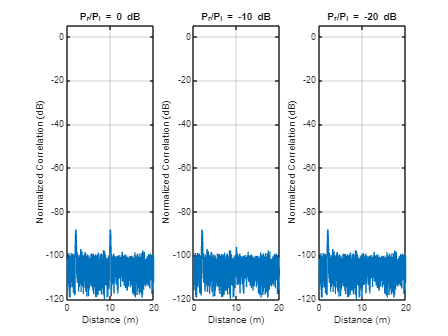

% Define simulation parameters
distances = linspace(0, 20, 2000); % Distance vector from 0 to 20 meters
internal_reflection_dist = 2; % Internal reflection at 2 meters
target_dist = 10; % Target at 10 meters
power_internal_reflection = 1.5e-9; % Power of internal reflection in watts (1.5 nW)

% Powers of the backscattered signal in watts, relative to internal reflection
power_backscattered = [1.5e-9, 0.15e-9, 0.015e-9];

% Noise level (consider practical SNR less than 15 dB)
noise_level = power_internal_reflection / 10^(15/10);

% Generate the internal reflection peak (Gaussian centered at 2m)
internal_reflection_signal = power_internal_reflection * exp(-((distances - internal_reflection_dist).^2) / (0.1^2));

% Generate noise
noise = noise_level * randn(1, length(distances));

% Initialize array to hold all signal values
signal = zeros(length(distances), length(power_backscattered));

% Generate signals for each power level of the backscattered signal
for i = 1:length(power_backscattered)
    % Backscattered signal (Gaussian centered at 10m)
    backscattered_signal = power_backscattered(i) * exp(-((distances - target_dist).^2) / (0.1^2));
    
    % Total signal is the sum of internal reflection, backscattered signal, and noise
    total_signal = internal_reflection_signal + backscattered_signal + noise;
    
    % Convert to dB scale for plotting, ensure no log of zero occurs
    signal(:, i) = 10 * log10(abs(total_signal) + 1e-12);
end

% Plot the results
figure;
for i = 1:length(power_backscattered)
    subplot(1, 3, i);
    plot(distances, signal(:, i));
    title(['P_r/P_i = ' num2str(10 * log10(power_backscattered(i) / power_internal_reflection)) ' dB']);
    xlabel('Distance (m)');
    ylabel('Normalized Correlation (dB)');
    ylim([-120 5]); % Adjust y-limits to match the scale of your figure
    grid on;
end